# Linear Control Design II - Group Work Problem Module 14

## Description

**Problems**

The assignment deals with the multi-variable controller design for the TITO (two-inputs two-outputs) model of the aircraft introduced in Group Work Module 10.

The state space representation of the model is


$$ \pmatrix
    { \dot{\beta}\cr
   \dot{r}\cr
   \dot{p}\cr
   \dot{\phi}}
 =    \left(\begin{array}{cccc} -0.0558 & -0.9968 & 0.0802 & 0.0415\\ 0.598 & -0.115 & -0.0318 & 0\\ -3.05 & 0.388 & -0.465 & 0\\ 0 & 0.0805 & 1.0 & 0 \end{array}\right)
 \pmatrix{
   \beta \cr
   r\cr
   p\cr
   \phi}
 
 +
\left(\begin{array}{cc} 0.00729 & 0.00001\\ -0.475 & 0.123\\ 0.153 & 1.063\\ 0 & 0 \end{array}\right)
 \pmatrix{
   \delta r\cr
   \delta a
  } \\
 \mathbf{y}=\pmatrix{
  0 \ 1 \ 0 \ 0\cr
  0 \ 0 \ 0 \ 1
 }
 \pmatrix{  \beta\cr
   r\cr
   p\cr
   \phi
  }$$


**Problem 1** 	Assess if the open loop system is controllable. Is the system stabilizable?.

**Solution****:**

% Your solution goes here:
format short g

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0];
B = [0.00729   1e-5; 
    -0.475     0.123; 
     0.153     1.063;     
     0         0];
C = [0 1 0 0;
     0 0 0 1];
D = zeros(2,2);

Mc = ctrb(A,B)

Mc =     0.0073    0.0000    0.4853   -0.0374   -0.0985    0.0586   -0.4044    0.0050
   -0.4750    0.1230    0.0541   -0.0479    0.2928   -0.0026   -0.0503    0.0257
    0.1530    1.0630   -0.2777   -0.4466   -1.3302    0.3030    1.0327   -0.3206
         0         0    0.1148    1.0729   -0.2733   -0.4505   -1.3066    0.3028


rank(Mc)

ans =      4


It's controllable.

**Problem 2** A multi-variable full state feedback controller $\mathbf{u} = -\mathbf{K}\mathbf{x} + \mathbf{r}$ for the aircraft is to be designed. The continuous time closed-loop system's eigenvalues have to be placed at the following location in the left half plane


$$ \lambda=\left\{\begin{array}{l}
	  -0.5\\ -0.6\\ -0.5\pm 0.5\rm{j}
	 \end{array}$$


Design a discrete time controller and use the sampling period ${0.1}$$s$. Find the gain matrix $\mathbf{K}$ for the controller by applying the Matlab function *place*. Check the position of the eigenvalues of the closed-loop system. Are the design requirements fulfilled?

**Solution****:**

%% Continous Controller
pl = [-0.5 -0.6 -0.5+0.5i -0.5-0.5i];
K = place(A,B,pl)

K =    -1.4256   -1.7645   -0.6312   -0.3629
   -2.3647    0.1105    0.6768    0.3143


lambda = eig(A-B*K)

lambda =   -0.5000 + 0.5000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -0.6000 + 0.0000i


%% Discrete controller
Ts = 0.1;
F = expm(A*Ts);
[F,G] = c2d(A,B,Ts);
pl_disc = exp(pl*Ts);
K_disc = place(F,G,pl_disc)

K_disc =    -1.4184   -1.6498   -0.5942   -0.3454
   -2.3737    0.2459    0.6337    0.2932


% it's wrong to use eig(F-G*K_disc) to verify
lambdaA = (1/Ts)*log(eig(F-G*K_disc))

lambdaA =   -0.5000 + 0.5000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -0.6000 + 0.0000i


**Problem 3 ** Add the controller to the Simulink model and carry out a simulation with the function in Figure1 as reference signal for both inputs, but one at a time. Plot the states, outputs and control signals, i.e. the rudder angle and the aileron angle.

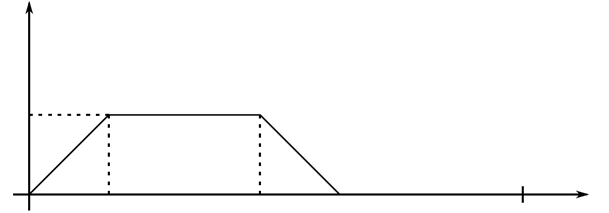

**Solution****:**

## **Continous **

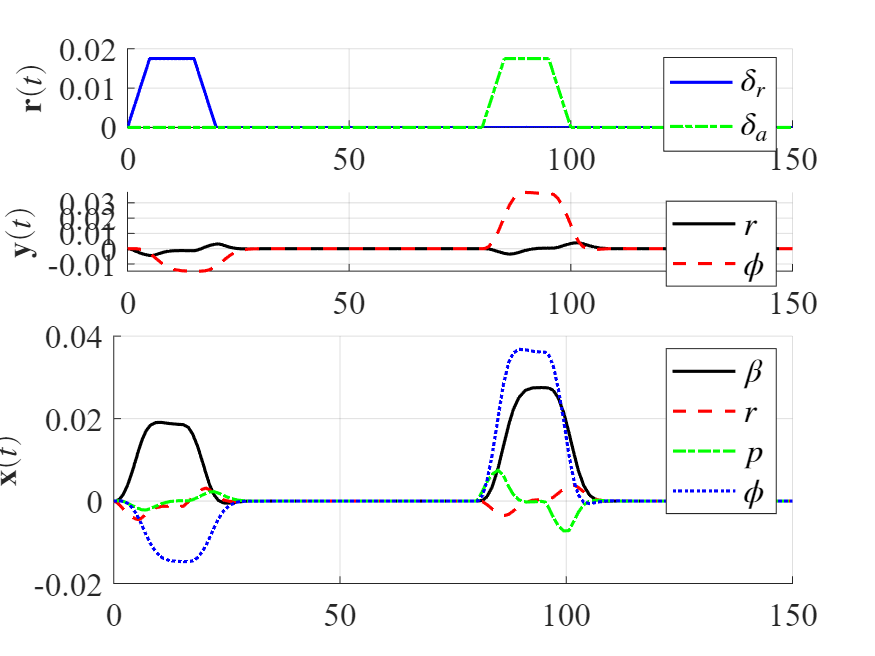

% Your solution goes here:
% generation of reference signals
t = 0:0.1:150;
t1 = 0:0.1:5;
r1 = t1*0.0175/5;
r3 = 0.0175+((-0.0175/5)*t1);
r = [r1 0.0175*ones(1,99) r3 zeros(1,1300)];
ra = [zeros(1,800) r1 0.0175*ones(1,99) r3 zeros(1,500)];
input = [t' r' ra'];
[ts, xs, ys] = sim("My747m14",150,[],input);

% plotting the results
figure

% plot input signals
h1 = subplot(4,1,1);
set(h1, 'FontName', 'Times', 'FontSize',16);
hold on
grid on
plot(t,r,'b',t,ra,'-.g','LineWidth',1.5)
ylabel('$\mathbf{r}(t)$','FontName','times','FontSize',16,'interpreter','latex')
l = legend('$\delta_r$','$\delta_a$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

% plot output
h2 = subplot(4,1,2);
set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(ts, ys(:,1),'k', ts, ys(:,2),'--r', 'LineWidth',1.5)
ylabel('$\mathbf{y}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$r$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

% plot states
h3 = subplot(4,1,3:4); 
set(h3,'FontName','times','FontSize',16)
hold on, grid on
plot(ts, xs(:,1), 'k', ts, xs(:,2), '--r', ts, xs(:,3), '-.g', ts, xs(:,4),':b','LineWidth',1.5)
ylabel('$\mathbf{x}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$\beta$','$r$','$p$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

## Discrete

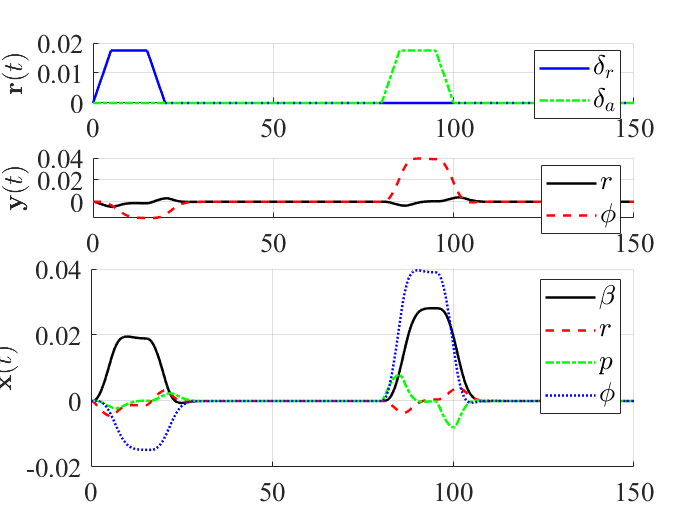

[td, xd, yd] = sim('My747m14d',150,[],input);
figure, h4 = subplot(4,1,1); set(h4,'FontName','times','FontSize',16)
hold on, grid on
plot(t,r,'b',t,ra,'-.g','LineWidth',1.5)
ylabel('$\mathbf{r}(t)$','FontName','times','FontSize',16,'interpreter','latex')
l = legend('$\delta_r$','$\delta_a$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

h5 = subplot(4,1,2); set(h5,'FontName','times','FontSize',16)
hold on, grid on
plot(td,yd(:,1),'k',td,yd(:,2),'--r','LineWidth',1.5)
ylabel('$\mathbf{y}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$r$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

h6 = subplot(4,1,3:4); set(h6,'FontName','times','FontSize',16)
hold on, grid on
plot(td,xd(:,1),'k',td,xd(:,2),'--r',td,xd(:,3),'-.g',td,xd(:,4),':b','LineWidth',1.5)
ylabel('$\mathbf{x}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$\beta$','$r$','$p$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

**Problem 4 ** Now suppose that the aircraft's rudder and aileron servos are slower than we thought. Add a $1 \ s$ time constant to each of the continuous control inputs and see what happens. How could the problem be solved?

**Solution****:**

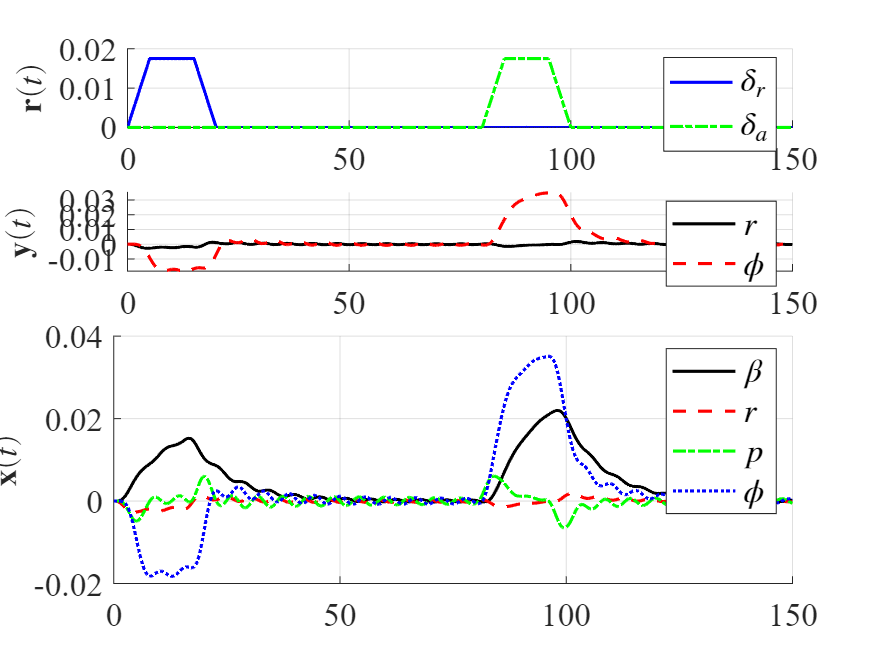

% Your solution goes here:
T = 0.1;
Kd = K_disc;
[tdn, xdn, ydn] = sim('My747m14ddelay.slx',150,[],input);
%[tdn, xdn, ydn] = sim('lat747mod10dn.mdl',150,[],input);
figure, h7 = subplot(4,1,1); set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(t,r,'b',t,ra,'-.g','LineWidth',1.5)
ylabel('$\mathbf{r}(t)$','FontName','times','FontSize',16,'interpreter','latex')
l = legend('$\delta_r$','$\delta_a$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

h8 = subplot(4,1,2); set(h8,'FontName','times','FontSize',16)
hold on, grid on
plot(tdn,ydn(:,1),'k',tdn,ydn(:,2),'--r','LineWidth',1.5)
ylabel('$\mathbf{y}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$r$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

h9 = subplot(4,1,3:4); set(h9,'FontName','times','FontSize',16)
hold on, grid on
plot(tdn,xdn(:,1),'k',td,xdn(:,2),'--r',tdn,xdn(:,3),'-.g',tdn,xdn(:,4),':b','LineWidth',1.5)
ylabel('$\mathbf{x}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$\beta$','$r$','$p$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

**Problem 5 **Find the stationary output $\mathbf{y}_0$ for the closed-loop system and for the constant reference inputs $\mathbf{r}(k)=\left[\matrix{0.1 \   0}\right]^\mathrm{T}$ and $\mathbf{r}(k)=\left[\matrix{0  \ 0.1}\right]^\mathrm{T}$. Does $y_0$ depend on the eigenvalue placement? (`Hint: For a stationary state the discrete state vector is constant, i.e.` $\mathbf{x}(k+1)=\mathbf{x}(k)$).


$$y_0=Cx_0=CQ^-1Gr_0$$


**Solution****:**

% Your solution goes here:
r0 = [0.1;0];
Q = eye(4,4)-F+G*K_disc;
x0 = inv(Q)*G*r0

x0 =     0.1082
   -0.0080
    0.0006
   -0.0847


y0 = C*x0

y0 =    -0.0080
   -0.0847



r0 = [0;0.1];
Q = eye(4,4)-F+G*K_disc;
x0 = inv(Q)*G*r0

x0 =     0.1604
    0.0026
   -0.0002
    0.2233


y0 = C*x0

y0 =     0.0026
    0.2233
